%Scaled correlation analysis: Spike-Triggered Average (STA)
%Example of using the ComputeScaledSTA.dll library
%Author: Raul C. Muresan, 17.05.2007
%ATTENTION: If you supply the time stamps and the samples for a single trial, make sure that the time stamps are relative to the beginning of the trial
%           The time stamps and samples should be given in vectors in row format (values along the row, not along the column)
%           The sampling frequency of the continuous and binary signals must match

clear all;

%Some example values for the parameters
iTrialLength = 2000;        %Suppose we have a sampling frequency of 1 kHz. We choose a trial length of 2000 ms.
iScaleWindow = 40;          %The size of the scale segment for the scaled correlation analysis
iCorrelationWindow = 100;   %We are interested in a scaled correlogram of -100..100 ms.
iTrialNumber = 20;          %Suppose we have 20 trials
fFiringRate = 10;           %Suppose an average firing rate of 10 Hz => 20 Spikes per trial

%Produce some random time stamps in the neuron
iaTimeStampsNeuronA = sort(round(iTrialLength * iTrialNumber * rand(1,iTrialNumber * fFiringRate * iTrialLength / 1000)),'ascend');

%Produce an LFP
daLFPSamplesB = zeros(1,iTrialLength*iTrialNumber);
for i=1:iTrialLength*iTrialNumber;
    daLFPSamplesB(i) = sin(2*3.14/50*1000*i);
end


% We have two options to compute the scaled spike-triggered average.
% I. If the trials follow one after another in the spike and LFP vector then we can call only once the function ComputeScaledSTA and it will return the scaled correlogram averaged over trials.
% II. If we do not have all the trials in the same spike and LFP vector then we would like to compute the correlation separately for each trial and eventually average over them.


% **************************************************************************************************************************************************************************************************************************************************
%%%%%%%%%%%%% Option I: the trials are in the spike and LFP vector one after another in a continuous sequence %%%%%%%%%%%%%%%%%%%%%
%Compute the spike triggered average
%The function expects 6 parameters:
% 	1. ScaleWindow          - Integer Number; Scalar					- The size of the scale segment window used in scaled correlation analysis
% 	2. CorrelationWindow	- Integer Number; Scalar					- The size of the correlation window (eg. 80 for a scaled correlation with lags of -80..+80); use the same units as the sampling of your time stamps and samples
% 	3. TrialLength			- Integer Number; Scalar					- The size of the trial in sampling units
% 	4. TimeStampsA			- Vector of Integer Numbers: Time Stamps	- The vector holding the time stamps of events in the binary signal
% 	5. SamplesB				- Vector of Double Numbers: Samples			- The vector holding the samples of the continuous signal
% 	6. UseFisherZTransform	- Integer Number; Scalar					- Set to 1 if you want to use the Fisher's Z Transform when the correlation	coefficients are averaged
%   ATTENTION: the function returns NaN (Not a Number) values if there is no matching time stamp of an event in the binary signal for a given scale segment
%Return values:
% 	R = matrix(3,2*CorrW+1)	- A return matrix with 3 rows and 2*piCorrelationWindow+1 columns. The matrix contains:
%                               - R(1,...) - The Scaled Cross Correlogram - Vector of Doubles A vector containing the cross correlogram, having 2 * piCorrelationWindow + 1 elements; lag 0 is at position piCorrelationWindow + 1 in Matlab
%                                 Returns NaN (Not a Number) values bins for which correlation could not be defined (missing data, etc...)
%                               - R(2,...) - The sum of the correlation coefficients for a given bin; contains NaN (Not a Number) values bins for which correlation could not be defined (missing data, etc...).
% 								- R(3,...) - The count of valid correlation coefficients for a given bin, that are used to compute the scaled correlogram;
% 								=> R(1,i) = R(2,i) / R(3,i);

ReturnMatrix = ComputeScaledSTA(iScaleWindow,iCorrelationWindow,iTrialLength,iaTimeStampsNeuronA,daLFPSamplesB,0);

Entry in scaled STA function...
Scale segment size: 40
Correlation window: 100
Trial length: 2000
Time stamps: 400
Samples: 40000
Scaled correlation computed successfully!


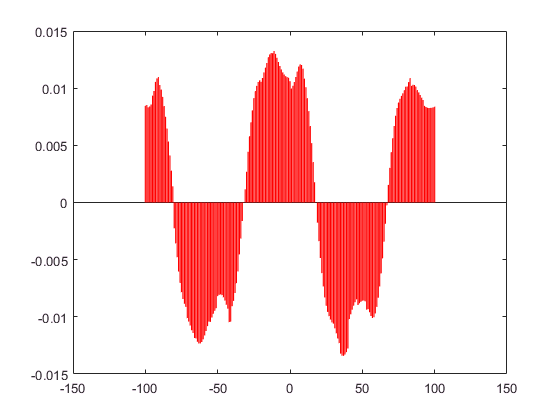


% Get the scaled STA
daSTA = ReturnMatrix(1,:);

%Plot the scaled STA correlogram
figure(1);
x = -100:1:100;
bar(x,daSTA,'r');



% % **************************************************************************************************************************************************************************************************************************************************
% %%%%%%%%%%%%% Option II: We want to go trial by trial and conpute the correlogram on each %%%%%%%%%%%%%%%%%%%%%
% % In this case, instead of averaging the scaled correlograms for each trial, we should sum up the coefficients of correlation for each bin and then divide by their total count (see below)
% % Averaging the scaled correlations is also possible but yields a bit more noisier results than the method with the sums and counts of correlation coefficients
% 
% daCoefficientSums   = zeros(1,2*iCorrelationWindow+1);
% daCoefficientCounts = zeros(1,2*iCorrelationWindow+1);
% 
% %For each trial, do:
% for trial=1:iTrialNumber
%     
%     %Compute the indexes where trial for the continuous variable starts and finishes
%     idxContFrom = (trial-1)*iTrialLength + 1;
%     idxContTo   = trial*iTrialLength;
%     
%     %Extract the trial from continuous signal
%     daTrialContinuous = daLFPSamplesB(idxContFrom:idxContTo);
%     
%     %Compute the indexes where the trial in the time stamp vector (time stamps of events from the binary signal) starts and ends
%     idxBinaryFrom = find(iaTimeStampsNeuronA >= (trial-1)*iTrialLength,1,'first');
%     idxBinaryTo = find(iaTimeStampsNeuronA < trial*iTrialLength,1,'last');
%     
%     %Extract the trial from the time stamp vector
%     daTrialBinary = iaTimeStampsNeuronA(idxBinaryFrom:idxBinaryTo);
%     
%     %Align the time stamps to the beginning of the trial
%     daTrialBinary = daTrialBinary - (trial-1)*iTrialLength;
%     
%     %Compute the spike triggered average on the trial
%     %The function expects 6 parameters:
%     % 	1. ScaleWindow          - Integer Number; Scalar					- The size of the scale segment window used in scaled correlation analysis
%     % 	2. CorrelationWindow	- Integer Number; Scalar					- The size of the correlation window (eg. 80 for a scaled correlation with lags of -80..+80); use the same units as the sampling of your time stamps and samples
%     % 	3. TrialLength			- Integer Number; Scalar					- The size of the trial in sampling units
%     % 	4. TimeStampsA			- Vector of Integer Numbers: Time Stamps	- The vector holding the time stamps of events in the binary signal
%     % 	5. SamplesB				- Vector of Double Numbers: Samples			- The vector holding the samples of the continuous valued signal
%     % 	6. UseFisherZTransform	- Integer Number; Scalar					- Set to 1 if you want to use the Fisher's Z Transform when the correlation	coefficients are averaged
%     %   ATTENTION: the function returns NaN (Not a Number) values if there is no matching time stamp for a given scale segment
%     %Return values:
%     % 	R = matrix(3,2*CorrW+1)	- A return matrix with 3 rows and 2*piCorrelationWindow+1 columns. The matrix contains:
%     %                               - R(1,...) - The Scaled Cross Correlogram - Vector of Doubles A vector containing the cross correlogram, having 2 * piCorrelationWindow + 1 elements; lag 0 is at position piCorrelationWindow + 1 in Matlab
%     %                                 Returns NaN (Not a Number) values bins for which correlation could not be defined (missing data, etc...)
%     %                               - R(2,...) - The sum of the correlation coefficients for a given bin; contains NaN (Not a Number) values bins for which correlation could not be defined (missing data, etc...).
%     % 								- R(3,...) - The count of valid correlation coefficients for a given bin, that are used to compute the scaled correlogram;
%     % 								=> R(1,i) = R(2,i) / R(3,i);
%     ReturnMatrix = ComputeScaledSTA(iScaleWindow,iCorrelationWindow,iTrialLength,daTrialBinary,daTrialContinuous,0);
%     
%     %Retrieve sum of coefficients and their counts and treat the Not a Number cases
%     Sums = ReturnMatrix(2,:);
%     Sums(isnan(Sums)) = 0;    %Do not put NaNs to 0 when you average Scaled Correlograms (i.e. ReturnMatrix(1,:)). Here it is safe because we have the real count of valid coefficients and the average will be correct.
%     Counts = ReturnMatrix(3,:);
%     
%     %Sum up coefficients and counts   
%     daCoefficientSums   = daCoefficientSums + Sums;
%     daCoefficientCounts = daCoefficientCounts + Counts;
% end
% 
% %Compute the scaled correlogram by dividing the sum of correlation coefficients to their counts
% daSTA = daCoefficientSums ./ daCoefficientCounts;
% 
% %Plot the scaled cross-correlogram
% figure(2);
% x = -iCorrelationWindow:1:iCorrelationWindow;
% bar(x,daSTA,'r');